close("all"); clear; clc;

Cf = 128916;
Cr = 85944;
Izz = 1536.7;
lf = 1.06;
lr = 1.85;
m  = 1412;
params = [Cf,Cf,Izz,lf,lr,m].';

vx = 110/3.6;
x0 = [0,0,0,vx,0,0].';
A = dynamicBicycleStateMatrix(x0,params);
A = A(end-1:end,end-1:end);
B = dynamicBicycleInputMatrix(x0,params);
B = B(end-1:end,2);

state_names = [
    "v_y";
    "\omega_\psi"
    ];

state_units = [
    "m/s";
    "rad/s"
    ];

input_names = "\delta";

input_units = "rad";


C = [0,1];

plant = ss(A,B,C,0);
rank(ctrb(plant))

ans = 2


plant.StateName = state_names;
plant.StateUnit = state_units;
plant.InputName = input_names;
plant.InputUnit = input_units;
plant.OutputName = state_names(2);
plant.OutputUnit = state_units(2);
plant

plant =
 
  A = 
                        v_y  \omega_\psi
   v_y               -11.95       -25.83
   \omega_\psi        4.338       -24.96
 
  B = 
                \delta
   v_y           182.6
   \omega_\psi   177.8
 
  C = 
                        v_y  \omega_\psi
   \omega_\psi            0            1
 
  D = 
                \delta
   \omega_\psi       0
 
Continuous-time state-space model.



nx = size(plant.A,2);
nu = size(plant.B,2);
ny = size(plant.C,1);

K = realp("k",eye(nu,nx));
Ki = realp("ki",zeros(nu,ny));
Ka = [K,Ki];

Aa = [
    plant.a,zeros(nx,ny);
    plant.c,zeros(ny)
    ];

Ba = [
    plant.b;
    zeros(ny,nu)
    ];

Br = [
    zeros(nx,nu);
    -eye(ny,nu)
    ];

Ca = [plant.c,zeros(ny)];

sys0 = ss(Aa - Ba*Ka,Br,Ca,0);

options = hinfstructOptions;
% options.RandomStart = 10;
options.TargetGain = 0;
% options.UseParallel = true;
options.Display = "off";
[sys,gamma,info] = hinfstruct(sys0,options);

sys.StateName = [
    state_names;
    "z_1"
    ];

sys.StateUnit = [
    state_units;
    "rad/s"
    ];

sys.InputName = "\omega_{\psi,ref}";

sys.InputUnit = "rad/s";

sys.OutputName = plant.OutputName;
sys.OutputUnit = plant.OutputUnit;

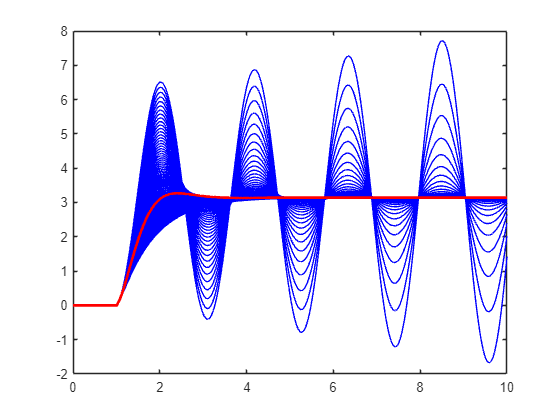

tf = 10;
ns = 1E03;
tspan = linspace(0,tf,ns);

t_step = 1;
u = pi.*(tspan > t_step);

vx = linspace(99,121,100)./3.6;
K = double(sys.Blocks.k);
Ki = double(sys.Blocks.ki);
Ka = [K,Ki];

fig = figure();
axe = axes(fig);

for i = 1:numel(vx)
    x0 = [0,0,0,vx(i),0,0].';
    A = dynamicBicycleStateMatrix(x0,params);
    A = A(end-1:end,end-1:end);
    B = dynamicBicycleInputMatrix(x0,params);
    B = B(end-1:end,2);

    Aa = [
        A,zeros(nx,ny);
        C,zeros(ny)
        ];

    Ba = [
        B;
        zeros(ny,nu)
        ];
    
    Br = [
        zeros(nx,nu);
        -eye(ny,nu)
        ];
    
    Ca = [C,zeros(ny)];
    
    sysi = ss(Aa - Ba*Ka,Br,Ca,0);
    [y,t] = lsim(sysi,u,tspan);
    hold(axe,"on");
    plot(axe,t,y,'b');
    hold(axe,"off");
end
[y,t] = lsim(sys,u,tspan);
hold(axe,"on");
plot(axe,t,y,'r',"LineWidth",2);
hold(axe,"off");
box(axe,"on");